clear;
f = 0.01034409; % friction coef for aerohockey table

%puck geometry
h = 1;
r = 1;
% omega = 1; % rad/s

% components of motion laws when type D trajectory
delta = 2 .* f .* h / r;
phi_0 = 0.975 + (0.992 - 0.975) .* delta;
alpha = cos(phi_0);
beta = sin(phi_0);

p_a = @(phi) integral2(@(ro, nu) ...
	(cos(phi) - sin(phi) .* (ro/r) .* sin(nu)).^2 .* ro ./ (pi .* ((sin(phi)).^2 * (ro/r).^2 - 2 .* (cos(phi)) .* (sin(phi)) .* (ro/r) .* sin(nu) + (cos(phi)).^2).^(3/2)),...
	0, r, 0, 2*pi)

p_a = function_handle with value:
    @(phi)integral2(@(ro,nu)(cos(phi)-sin(phi).*(ro/r).*sin(nu)).^2.*ro./(pi.*((sin(phi)).^2*(ro/r).^2-2.*(cos(phi)).*(sin(phi)).*(ro/r).*sin(nu)+(cos(phi)).^2).^(3/2)),0,r,0,2*pi)


p_b = @(phi) integral2(@(ro, nu) ...
	((ro/r) .* cos(nu)).^2 .* ro ./ (pi .* ((sin(phi)).^2 * (ro/r).^2 - 2 .* (cos(phi)) .* (sin(phi)) .* (ro/r) .* sin(nu) + (cos(phi)).^2).^(1/2)),...
	0, r, 0, 2*pi)

p_b = function_handle with value:
    @(phi)integral2(@(ro,nu)((ro/r).*cos(nu)).^2.*ro./(pi.*((sin(phi)).^2*(ro/r).^2-2.*(cos(phi)).*(sin(phi)).*(ro/r).*sin(nu)+(cos(phi)).^2).^(1/2)),0,r,0,2*pi)


p_a_hat = @(phi) integral2(@(ro, nu) ...
	( (sin(phi) .* (ro/r) - cos(phi) .* sin(nu)).^2) .*(ro/r).^2 .* ro ./ (pi .* ((sin(phi)).^2 * (ro/r).^2 - 2 .* (cos(phi)) .* (sin(phi)) .* (ro/r) .* sin(nu) + (cos(phi)).^2).^(3/2)),...
	0, r, 0, 2*pi)

p_a_hat = function_handle with value:
    @(phi)integral2(@(ro,nu)((sin(phi).*(ro/r)-cos(phi).*sin(nu)).^2).*(ro/r).^2.*ro./(pi.*((sin(phi)).^2*(ro/r).^2-2.*(cos(phi)).*(sin(phi)).*(ro/r).*sin(nu)+(cos(phi)).^2).^(3/2)),0,r,0,2*pi)


p_c_hat = @(phi) integral2(@(ro, nu) ...
	( sin(phi).^2 .* (ro/r).^2 .* cos(2*nu) + 2 .* cos(phi) .* sin(phi) .* (ro/r) .* sin(nu).^3 - cos(phi).^2 .* sin(nu).^2) .*(ro/r).^2 .* ro ./ (pi .* ((sin(phi)).^2 * (ro/r).^2 - 2 .* (cos(phi)) .* (sin(phi)) .* (ro/r) .* sin(nu) + (cos(phi)).^2).^(3/2)),...
	0, r, 0, 2*pi)

p_c_hat = function_handle with value:
    @(phi)integral2(@(ro,nu)(sin(phi).^2.*(ro/r).^2.*cos(2*nu)+2.*cos(phi).*sin(phi).*(ro/r).*sin(nu).^3-cos(phi).^2.*sin(nu).^2).*(ro/r).^2.*ro./(pi.*((sin(phi)).^2*(ro/r).^2-2.*(cos(phi)).*(sin(phi)).*(ro/r).*sin(nu)+(cos(phi)).^2).^(3/2)),0,r,0,2*pi)


p_c =@(phi) p_b(phi) - p_a_hat(phi)

p_c = function_handle with value:
    @(phi)p_b(phi)-p_a_hat(phi)


p_d = @(phi) 1 - delta.^2 .* sin(phi).^2 .* p_b(r, phi) .* p_c(r, phi);

p_a_res = [];
p_b_res = [];
p_a_hat_res = [];
p_c_hat_res = [];
p_c_res = [];
for phi = 0:0.01:pi/2
	p_a_data = p_a(phi);
	p_b_data = p_b(phi);
	p_a_hat_data = p_a_hat(phi);
	p_c_hat_data = p_c_hat(phi);
	p_c_data = p_c(phi);
	p_a_res = [p_a_res; real(p_a_data)];
	p_b_res = [p_b_res; real(p_b_data)];
	p_a_hat_res = [p_a_hat_res; real(p_a_hat_data)];
	p_c_hat_res = [p_c_hat_res; real(p_c_hat_data)];
	p_c_res = [p_c_res; real(p_c_data)];
end

p_a_res = clean_data(p_a_res);
p_b_res = clean_data(p_b_res);
p_a_hat_res = clean_data(p_a_hat_res);
p_c_hat_res = clean_data(p_c_hat_res);
p_c_res = clean_data(p_c_res);

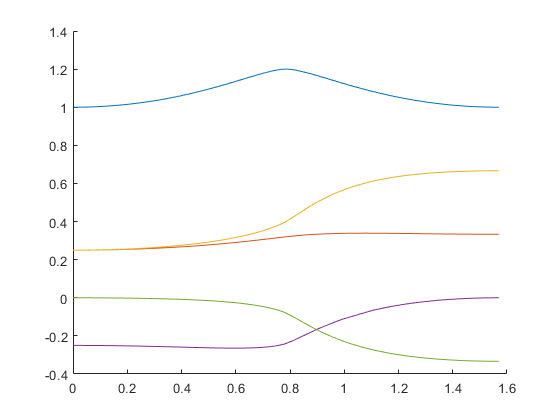

cla;
figure(1);
hold on
phi = 0:0.01:pi/2;
plot(phi, p_a_res);
plot(phi, p_b_res);
plot(phi, p_a_hat_res);
plot(phi, p_c_hat_res);
plot(phi, p_c_res);
hold off

function list = clean_data(data)
	list = data;
	prev_idx = 0;
	next_idx = 0;
	for ii = 1:length(list)
		if isinf(list(ii)) || isnan(list(ii))
			prev_idx = ii-1;
			for jj = ii:length(list)
				if ~(isinf(list(jj)) || isnan(list(jj)))
					next_idx = jj;
					break
				end
			end
		end
		for kk = 1:(next_idx - prev_idx)
			derivative = (list(next_idx) - list(prev_idx)) / (next_idx - prev_idx);
			list(prev_idx+kk) = list(prev_idx) + kk * derivative;
		end
		ii = next_idx;
	end
end